# DD Costas Loop

*Careful, this plots could be misleading because with some probability and knowing differential qpsk has rotational symmetry,the phase estimate could seem to be far from the real phase offset*

## Constant phase offset, first order PLL, single SNR, gamma = 0.001

No doppler shift

Fixed EbN0

Constant phase offset

Acquisition and tracking (only avoiding noise)



 ===== RESULTS ======
Number of transmitted bits = 100000

Carrier frequency [MHz] = 450.00

Doppler (at t = 0) [Hz] = 0.00

Linear Doppler variation
Doppler variation rate [Hz] = 0.00

Rb = 1000000
Eb/N0: 7.99 dB 
Es/N0: 11.00 dB 
SER = 5.200000e-04
BER = 5.200000e-04
Phase mean = 6.281345e-01
Phase std = 2.686799e-02


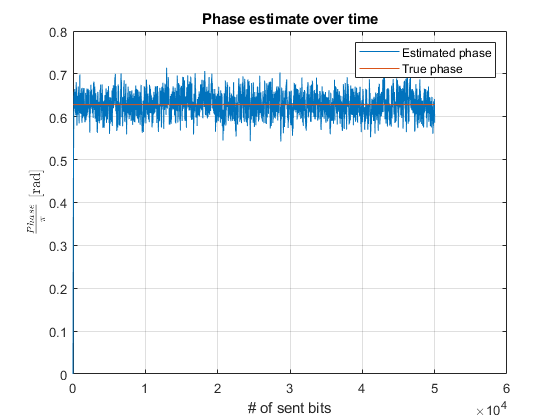

clear all;
close all;
N = 1e5;
gamma = 0.001; %For the loop filter;
phase_offset = pi/5;

tic
first_order_costas_decision(6.3,450e6,1e6,true,false,N,0,phase_offset,0,0,gamma);

toc

Elapsed time is 49.338130 seconds.


## Constant phase offset, first order PLL, single SNR, gamma = 0.01

No doppler shift

Fixed EbN0

Constant phase offset

Acquisition and tracking (only avoiding noise)



 ===== RESULTS ======
Number of transmitted bits = 100000

Carrier frequency [MHz] = 450.00

Doppler (at t = 0) [Hz] = 0.00

Linear Doppler variation
Doppler variation rate [Hz] = 0.00

Rb = 1000000
Eb/N0: 7.99 dB 
Es/N0: 11.00 dB 
SER = 7.400000e-04
BER = 7.200000e-04
Phase mean = 6.277781e-01
Phase std = 7.651472e-02


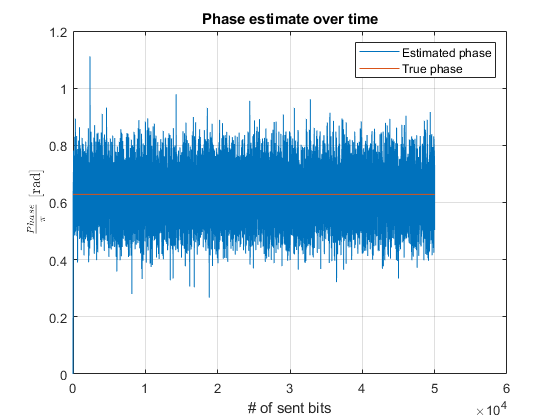

clear all;
close all;
N = 1e5;
gamma = 0.01; %For the loop filter;
phase_offset = pi/5;

tic
first_order_costas_decision(6.3,450e6,1e6,true,false,N,0,phase_offset,0,0,gamma);

toc

Elapsed time is 51.555371 seconds.


## Constant phase offset, first order PLL, single SNR, gamma = 0.1

No doppler shift

Fixed EbN0

Constant phase offset

Acquisition and tracking (only avoiding noise)



 ===== RESULTS ======
Number of transmitted bits = 100000

Carrier frequency [MHz] = 450.00

Doppler (at t = 0) [Hz] = 0.00

Linear Doppler variation
Doppler variation rate [Hz] = 0.00

Rb = 1000000
Eb/N0: 7.99 dB 
Es/N0: 11.00 dB 
SER = 7.494000e-01
BER = 1.622000e-01
Phase mean = -1.237815e+02
Phase std = 7.414765e+01


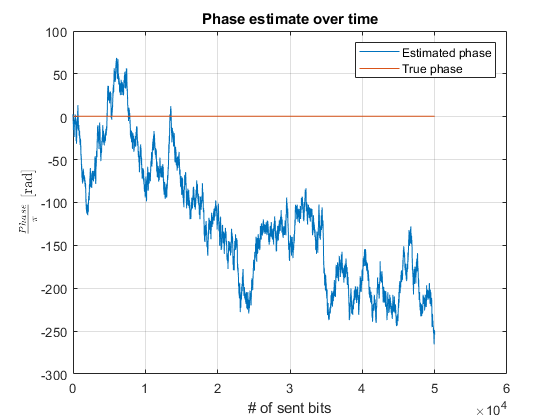

clear all;
close all;
N = 1e5;
gamma = 0.1; %For the loop filter;
phase_offset = pi/5;

tic
first_order_costas_decision(6.3,450e6,1e6,true,false,N,0,phase_offset,0,0,gamma);

toc

Elapsed time is 49.893800 seconds.


## Conclusiones

Hay que tener un gamma lo suficientemente grande como para adquirir la fase rápido pero lo más pequeño posible para hacer frente al ruido

## Constant phase offset, first order PLL, several SNR

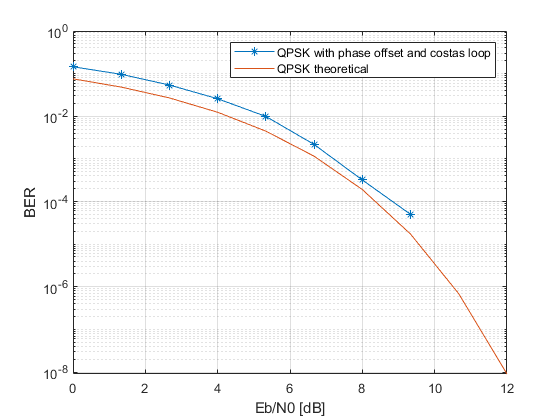

clear all;
close all;
N = 10;
N_b = 1e5;
gamma = 0.001; %For the loop filter;
phase_offset = pi/5;

tic
EbN0_dB = linspace(0,12,N);
EbN0 = 10.^(EbN0_dB/10);
ber = zeros(1,N);
ber_t = zeros(1,N);

for k=1:N
    a = qfunc(sqrt(2*EbN0(1,k)));
    ber_t(1,k)=(2*a-a^2)/2;
end

for k=1:N
    [~, ber(1,k)] = first_order_costas_decision(EbN0(1,k),450e6,1e6,false,false,N_b,0,phase_offset,0,0,gamma);
end
figure;
semilogy(EbN0_dB,ber,'*-');
grid on;
hold on;
semilogy(EbN0_dB,ber_t);
xlabel("Eb/N0 [dB]");
ylabel("BER");
legend("QPSK with phase offset and costas loop","QPSK theoretical");


toc

Elapsed time is 513.741084 seconds.


## Constant phase offset, first order PLL, several SNR different gamma

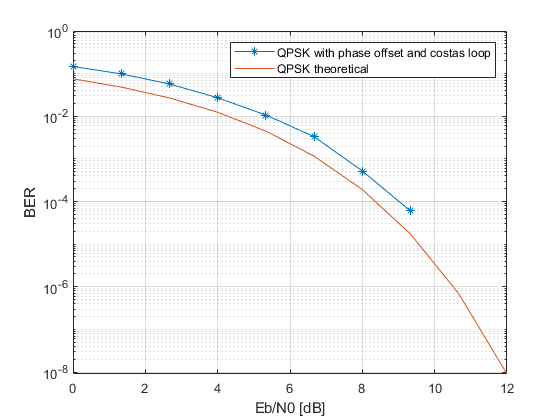

clear all;
close all;
N = 10;
N_b = 1e5;
gamma = 0.01; %For the loop filter;
phase_offset = pi/5;

tic
EbN0_dB = linspace(0,12,N);
EbN0 = 10.^(EbN0_dB/10);
ber = zeros(1,N);
ber_t = zeros(1,N);

for k=1:N
    a = qfunc(sqrt(2*EbN0(1,k)));
    ber_t(1,k)=(2*a-a^2)/2;
end

for k=1:N
    [~, ber(1,k)] = first_order_costas_decision(EbN0(1,k),450e6,1e6,false,false,N_b,0,phase_offset,0,0,gamma);
end
figure;
semilogy(EbN0_dB,ber,'*-');
grid on;
hold on;
semilogy(EbN0_dB,ber_t);
xlabel("Eb/N0 [dB]");
ylabel("BER");
legend("QPSK with phase offset and costas loop","QPSK theoretical");

toc